% Параметры системы
M = 20; % масса тележки
m1 = 2; % масса 1-го груза
m2 = 1; % масса 2-го груза
l1 = 1; % длина 1-го маятника
l2 = 2; % длина 2-го маятника
g = 10; % ускорение свободного падения

% ВСВ
A = [0 1 0 0 0 0;
     0 0 m1*g/M 0 m2*g/M 0;
     0 0 0 1 0 0;
     0 0 (M+m1)*g/(M*l1) 0 m2*g/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 m1*g/(M*l2) 0 (M+m2)*g/(M*l2) 0];

B = [0;
     1/M;
     0;
     1/(M*l1);
     0
     1/(M*l2)];

D = [0 0;
     1/(M*l1) 1/(M*l2);
     0 0;
     1/l1^2*(1/M+1/m1) 1/(M*l1*l2);
     0 0;
     1/(M*l1*l2) 1/l2^2*(1/M+1/m2)];

C = [1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 1 0];

% начальные условия:
x_0 = 1;
v_0 = 0;
phi1_0 = 0.045;
w1_0 = 0;
phi2_0 = 0.045;
w2_0 = 0;
x0 = [x_0, v_0, phi1_0, w1_0, phi2_0, w2_0];

% регулятор
Q = 1*eye(6,6)

Q =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


R = 1

R = 1

[K, P, S] = lqr(A, B, Q, R)

K = 1.0e+03 *

    0.0010    0.0066    1.5231    0.4753   -1.6086   -0.7238


P = 1.0e+05 *

    0.0001    0.0002    0.0048    0.0015   -0.0072   -0.0032
    0.0002    0.0012    0.0301    0.0095   -0.0448   -0.0201
    0.0048    0.0301    3.5762    1.1294   -4.5055   -2.0143
    0.0015    0.0095    1.1294    0.3567   -1.4259   -0.6374
   -0.0072   -0.0448   -4.5055   -1.4259    5.8650    2.6197
   -0.0032   -0.0201   -2.0143   -0.6374    2.6197    1.1702


S =   -0.2001 + 0.1921i
  -0.2001 - 0.1921i
  -2.2973 + 0.0000i
  -2.3288 + 0.0000i
  -3.4347 + 0.0000i
  -3.5381 + 0.0000i


K = -K

K = 1.0e+03 *

   -0.0010   -0.0066   -1.5231   -0.4753    1.6086    0.7238


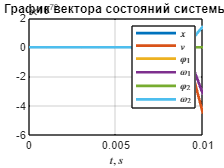


% вектор состояния
plot(out.x_nonlinear.Time, out.x_nonlinear.Data, LineWidth=2)
grid on
legend('$x$', '$v$', '$\varphi_1$', '$\omega_1$', '$\varphi_2$', '$\omega_2$','Interpreter','latex')
xlabel('$t,s$', 'Interpreter','latex')

title("График вектора состояний системы")

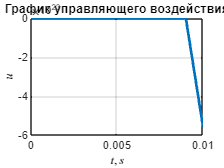

% управление 
plot(out.u.Time, out.u.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$u$', 'Interpreter','latex')
title("График управляющего воздействия")

% наблюдатель
Q = 1*eye(6,6)

Q =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


R = 1

R = 1

[P, L] = icare(A', C', Q, R, [], [], [])

P =     1.8523    1.5434    0.7020    2.5471    0.4039    1.0963
    1.5434    4.3918    3.7336   13.3205    1.7826    4.8611
    0.7020    3.7336    6.9274   23.7831    0.2908    1.8653
    2.5471   13.3205   23.7831   83.6523    1.8196    8.3647
    0.4039    1.7826    0.2908    1.8196    4.7709   11.0045
    1.0963    4.8611    1.8653    8.3647   11.0045   26.9556


L =     1.8523    1.5434    0.7020    2.5471    0.4039    1.0963
    0.7020    3.7336    6.9274   23.7831    0.2908    1.8653
    0.4039    1.7826    0.2908    1.8196    4.7709   11.0045


L = -L'

L =    -1.8523   -0.7020   -0.4039
   -1.5434   -3.7336   -1.7826
   -0.7020   -6.9274   -0.2908
   -2.5471  -23.7831   -1.8196
   -0.4039   -0.2908   -4.7709
   -1.0963   -1.8653  -11.0045


R = 1

R = 1

[K, P, S] = lqr(A, B, Q, R)

K = 1.0e+03 *

    0.0010    0.0066    1.5231    0.4753   -1.6086   -0.7238


P = 1.0e+05 *

    0.0001    0.0002    0.0048    0.0015   -0.0072   -0.0032
    0.0002    0.0012    0.0301    0.0095   -0.0448   -0.0201
    0.0048    0.0301    3.5762    1.1294   -4.5055   -2.0143
    0.0015    0.0095    1.1294    0.3567   -1.4259   -0.6374
   -0.0072   -0.0448   -4.5055   -1.4259    5.8650    2.6197
   -0.0032   -0.0201   -2.0143   -0.6374    2.6197    1.1702


S =   -0.2001 + 0.1921i
  -0.2001 - 0.1921i
  -2.2973 + 0.0000i
  -2.3288 + 0.0000i
  -3.4347 + 0.0000i
  -3.5381 + 0.0000i


K = -K

K = 1.0e+03 *

   -0.0010   -0.0066   -1.5231   -0.4753    1.6086    0.7238


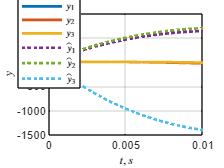

%выход
plot(out.y_linear.Time, out.y_linear.Data, LineWidth=2), grid on
hold on;
%оценка выхода
plot(out.y_linear_est.Time, out.y_linear_est.Data, LineWidth=2, LineStyle=":"), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
legend('$y_1$', '$y_2$', '$y_3$', '$\hat{y}_1$', '$\hat{y}_2$', '$\hat{y}_3$','Interpreter','latex')
legend("Position",[0.14663,0.5738,0.15222,0.34019])
hold off;

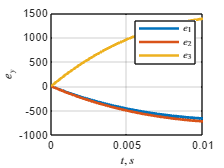


% ошибка наблюдателя
plot(out.y_linear.Time, out.y_linear.Data-out.y_linear_est.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$e_y$', 'Interpreter','latex')
legend('$e_1$', '$e_2$', '$e_3$', 'Interpreter','latex')

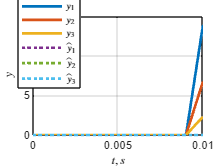


%выход
plot(out.y_nonlinear.Time, out.y_nonlinear.Data, LineWidth=2), grid on
hold on;
%оценка выхода
plot(out.y_nonlinear_est.Time, out.y_nonlinear_est.Data, LineWidth=2, LineStyle=":"), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
legend('$y_1$', '$y_2$', '$y_3$', '$\hat{y}_1$', '$\hat{y}_2$', '$\hat{y}_3$','Interpreter','latex')
legend("Position",[0.14663,0.5738,0.15222,0.34019])
hold off;

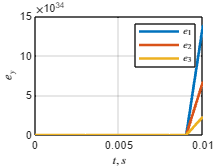


% ошибка наблюдателя
plot(out.y_nonlinear.Time, out.y_nonlinear.Data-out.y_nonlinear_est.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$e_y$', 'Interpreter','latex')
legend('$e_1$', '$e_2$', '$e_3$', 'Interpreter','latex')

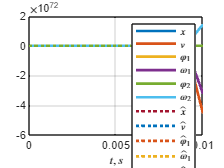



% вектор состояния
plot(out.x_nonlinear.Time, out.x_nonlinear.Data, LineWidth=2), grid on
hold on;
% оценка вектора состояния
plot(out.x_nonlinear_est.Time, out.x_nonlinear_est.Data, LineWidth=2, LineStyle=":"), grid on
xlabel('$t,s$', 'Interpreter','latex')
legend('$x$', '$v$', '$\varphi_1$', '$\omega_1$', '$\varphi_2$', '$\omega_2$', '$\hat{x}$', '$\hat{v}$', '$\hat{\varphi}_1$', '$\hat{\omega}_1$', '$\hat{\varphi}_2$', '$\hat{\omega}_2$', 'Interpreter','latex')
hold off;

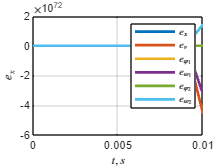

% ошибка наблюдателя
plot(out.x_nonlinear.Time, out.x_nonlinear.Data-out.x_nonlinear_est.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$e_x$', 'Interpreter','latex')
legend('$e_x$', '$e_v$', '$e_{\varphi_1}$', '$e_{\omega_1}$', '$e_{\varphi_2}$', '$e_{\omega_2}$','Interpreter','latex')